## fourier transformation 

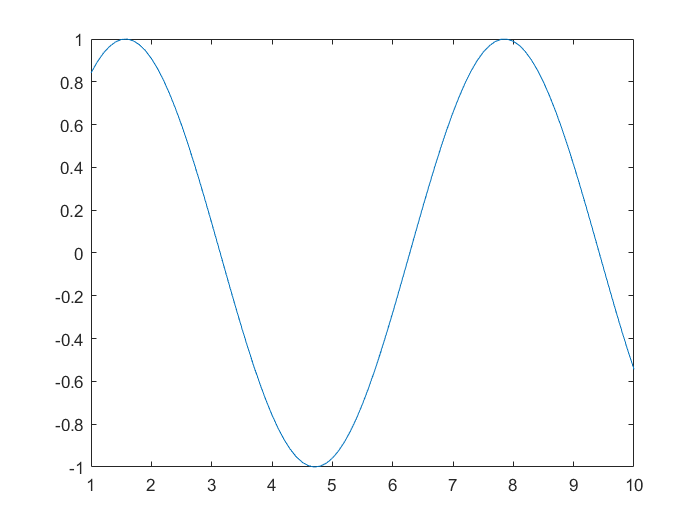

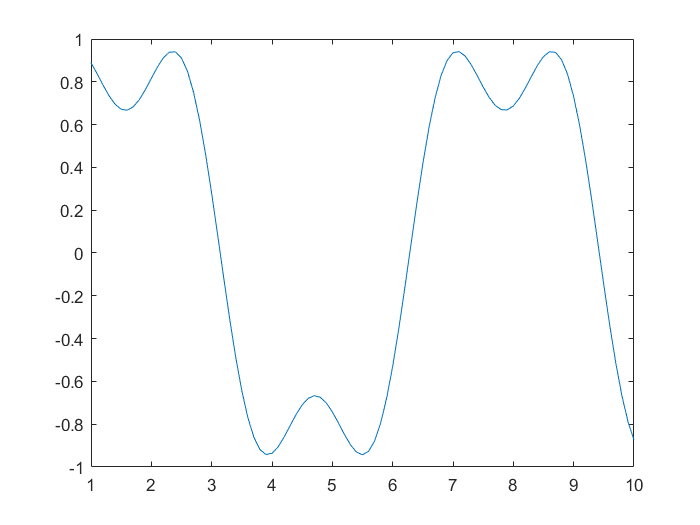

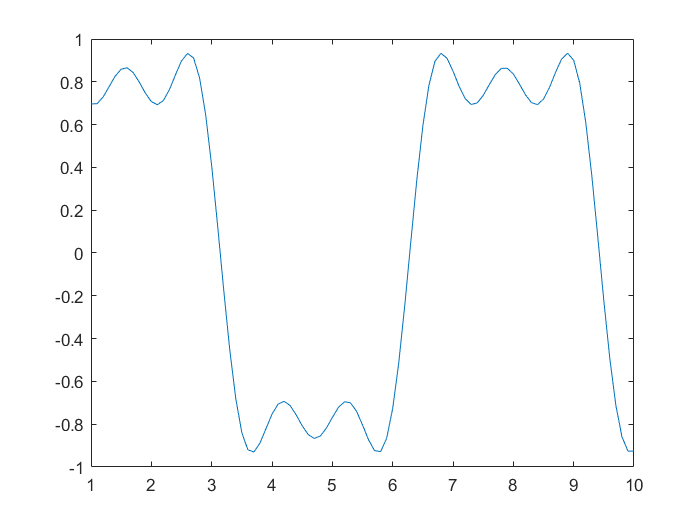

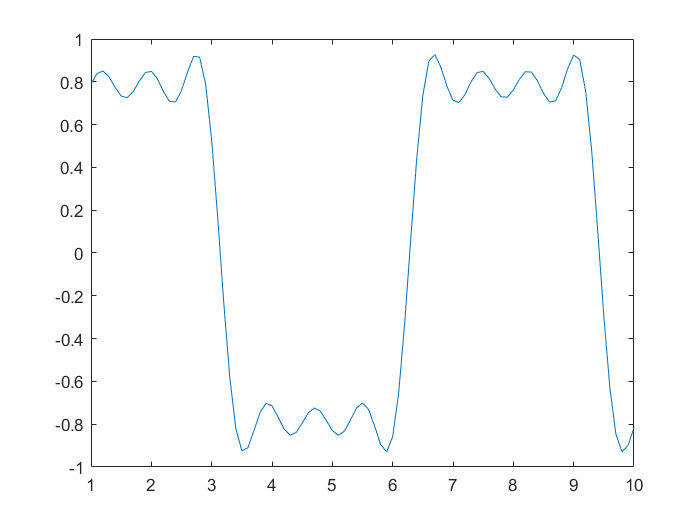

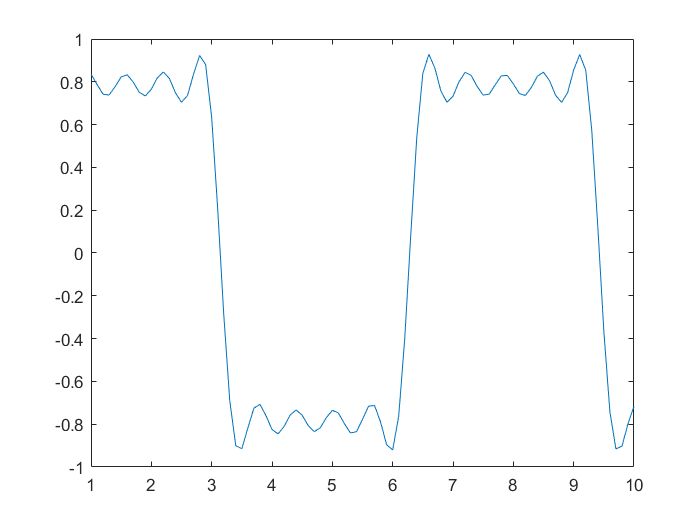

x = 1: 0.1: 10;
y =0;

for i = 0:4
    increment = 1/(2*i + 1) * sin((2*i + 1)*x);    % closer to square wave
    y = y + increment;
    figure; plot(x, y)
end

x = [2 3 4 5 6 7];
y = fft(x)

y =   27.0000 + 0.0000i  -3.0000 + 5.1962i  -3.0000 + 1.7321i  -3.0000 + 0.0000i  -3.0000 - 1.7321i  -3.0000 - 5.1962i


ifft(y)

ans =      2     3     4     5     6     7


a = ones(8);
fft2(a)

ans =     64     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0


fftshift(fft2(a))

ans =      0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0
     0     0     0     0    64     0     0     0
     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0


a = [100 200; 100 200];
b = repmat(a, 4, 4)

b =    100   200   100   200   100   200   100   200
   100   200   100   200   100   200   100   200
   100   200   100   200   100   200   100   200
   100   200   100   200   100   200   100   200
   100   200   100   200   100   200   100   200
   100   200   100   200   100   200   100   200
   100   200   100   200   100   200   100   200
   100   200   100   200   100   200   100   200


fft2(b)

ans =         9600           0           0           0       -3200           0           0           0
           0           0           0           0           0           0           0           0
           0           0           0           0           0           0           0           0
           0           0           0           0           0           0           0           0
           0           0           0           0           0           0           0           0
           0           0           0           0           0           0           0           0
           0           0           0           0           0           0           0           0
           0           0           0           0           0           0           0           0


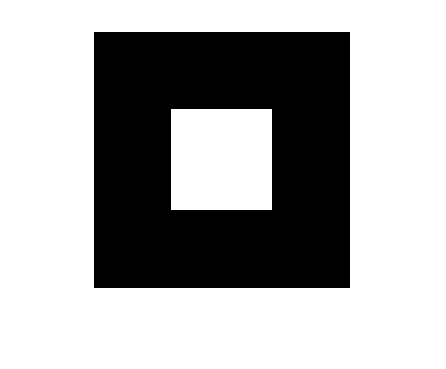

a = zeros(256, 256);
a(78: 178, 78: 178) = 1;
figure; imshow(a)

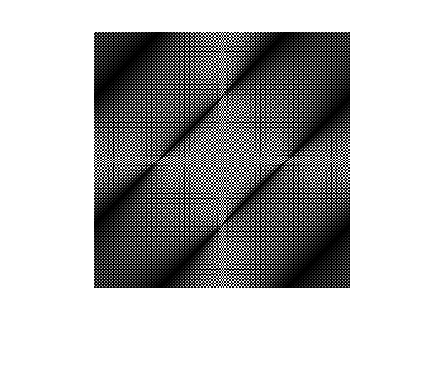


af = fftshift(fft2(a));
figure; imshow(af)

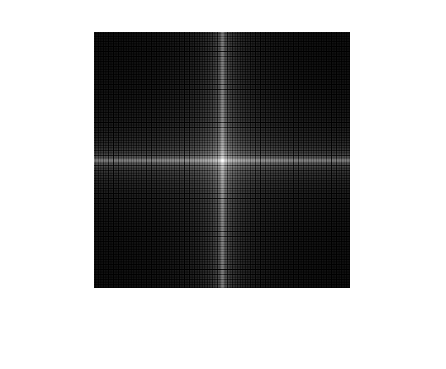


af1 = log(1 + abs(af));
fm = max(af1(:));
figure; imshow(af1/fm)

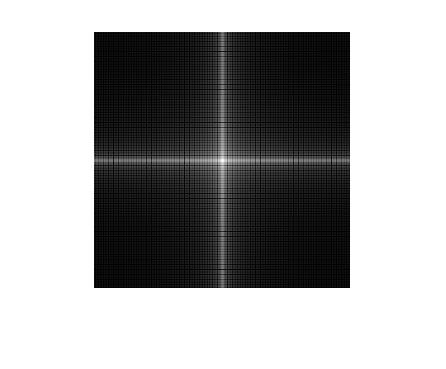

figure; imshow(mat2gray(af1))

## ringing effect

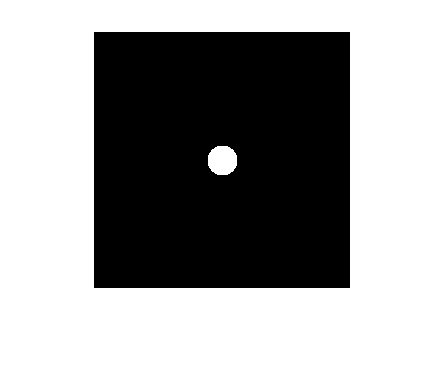

[x, y] = meshgrid(-128: 127, -128: 127);
z = sqrt(x.^2 + y.^2);
c = z < 15;
figure; imshow(c)

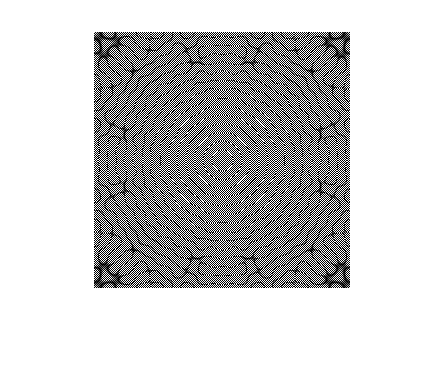


cf = fftshift(fft2(c));
figure; imshow(cf)

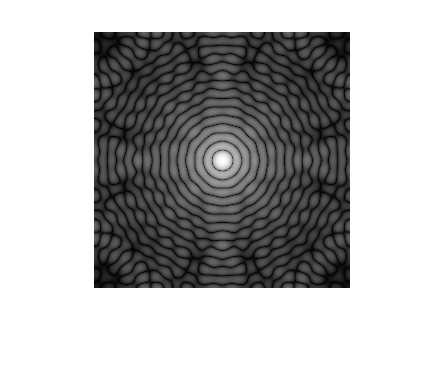


cf1 = log(1 + abs(cf));
m = max(cf1(:));
figure; imshow(cf1/m)

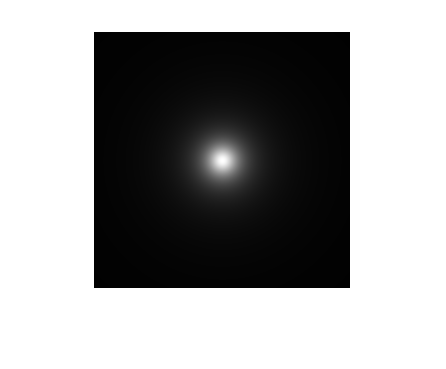

b = 1./(1 + (z./15).^2);
figure; imshow(b)

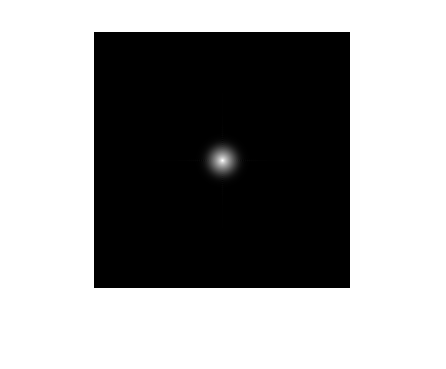


bf = fftshift(fft2(b));
bf1 = log(1 + abs(bf));
m = max(bf1(:));
figure; imshow(bf1/m)

## low pass filter in fourier domain

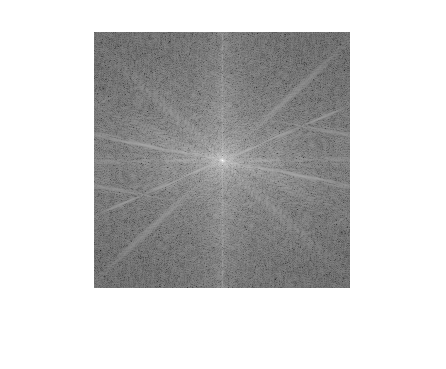

cm = imread('cameraman.tif');
cmf = fftshift(fft2(cm));
fftshow(cmf)

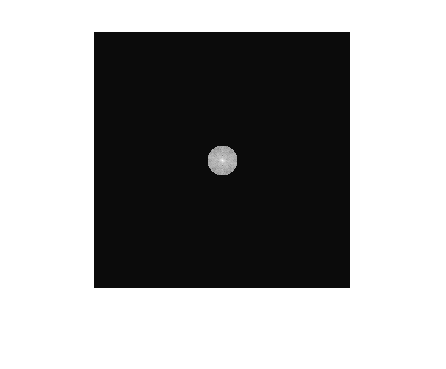

[x, y] = meshgrid(-128: 127, -128: 127);
z = sqrt(x.^2 + y.^2);
c = z < 15;

cmf1 = cmf.^c;
fftshow(cmf1)

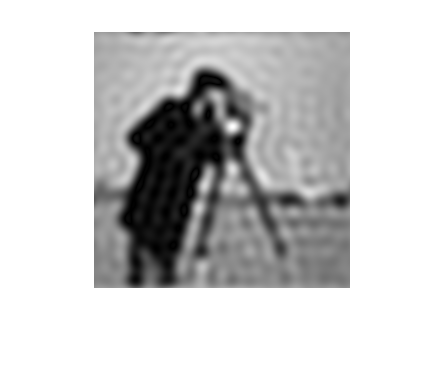


cmf1i = ifft2(cmf1);
ifftshow(cmf1i)

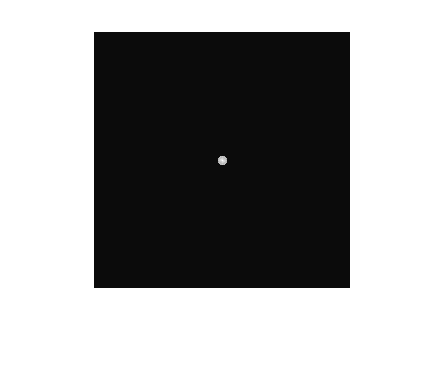

c1 = z < 5;

cmf1 = cmf.^c1;
fftshow(cmf1)

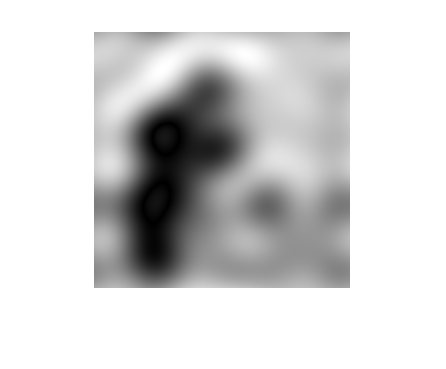


cmf1i = ifft2(cmf1);
ifftshow(cmf1i)

## high pass filter in fourier domain

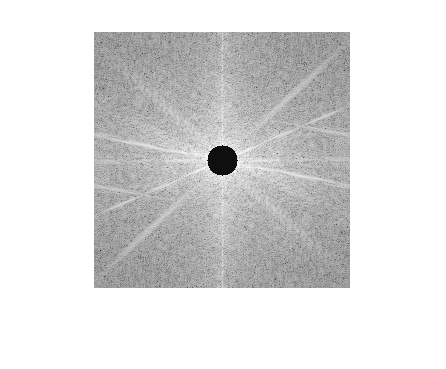

clear; clc;

[x, y] = meshgrid(-128: 127, -128: 127);
z = sqrt(x.^2 + y.^2);
c = z > 15;

a = imread('cameraman.tif');
af = fftshift(fft2(a));

hp = af.^c;
fftshow(hp)

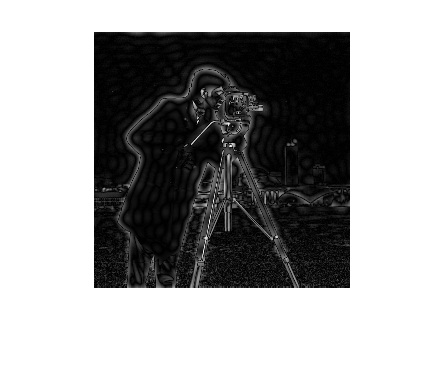


hpi = ifft2(hp);
ifftshow(hpi)

## high pass butterworth filter in frequency domain

## low pass butterworth filter in frequency domain

## low pass gaussian filter in frequency domain

## homomorphic filter